# Calculating the Fourier Series of a function with arbitrary period

In this MATLAB live script, we will define the square wave that has a period of 2 instead of specifically 2 pi, then we will calculate the Fourier coefficients by integration, and put it all together to obtain the approximate Fourier series for this function.

clear

## 1. Defining the function f(t)

syms t

First, we define our function's behaviour in the first period using Heaviside step functions:

f = 3 * (heaviside(t) - heaviside(t - 1))...
    + (-3) * (heaviside(t - 1) - heaviside(t - 2))

$$f = 3\,\mathrm{heaviside}\left(t-2\right)-6\,\mathrm{heaviside}\left(t-1\right)+3\,\mathrm{heaviside}\left(t\right)$$

And since we are now interested in arbitrary-period functions, store the value of the period (T=2) and the angular frequency (w=pi):

T=2

T = 2

w=pi

w = 3.1416

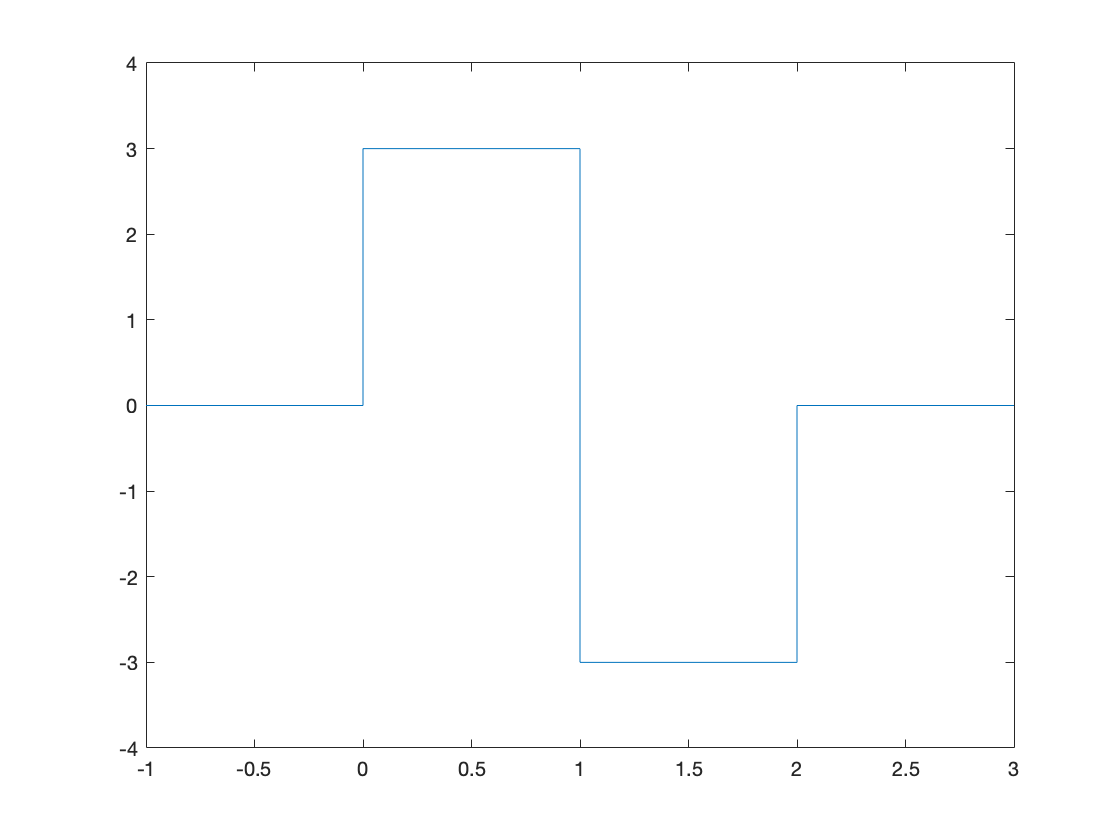

fplot(f, [-1, 3])
ylim([-4 4]) % zoom out a bit to view between -4<y<4

So we have used a combination of Heaviside functions to turn the two parts of the signal on and off at the necessary times.

## 2. Calculating Fourier Coefficients

Now we begin calculating Fourier coefficients. Note that we now:

- Integrate over the range 0<t<T

- Scale the integral by 2/T instead of 1/pi

- Have k*w*t inside the sin() and cos() instead of just k*t


a0 = int(f, t, 0, T)*2/T

$$a0 = 0$$


a1 = int(f * cos(w*t), t, 0, T)*2/T

$$a1 = 0$$


a2 = int(f * cos(2 * w * t), t, 0, T)*2/T

$$a2 = 0$$


a3 = int(f * cos(3 * w * t), t, 0, T)*2/T

$$a3 = 0$$


a4 = int(f * cos(4 * w * t), t, 0, T)*2/T

$$a4 = 0$$

Again, all the a_k terms are zero, as we saw that this is an odd function.

b1 = int(f * sin(w * t), t, 0, T)*2/T

$$b1 = \frac{12}{\pi }$$


b2 = int(f * sin(2 * w * t), t, 0, T)*2/T

$$b2 = 0$$


b3 = int(f * sin(3 * w * t), t, 0, T)*2/T

$$b3 = \frac{4}{\pi }$$


b4 = int(f * sin(4 * w * t), t, 0, T)*2/T

$$b4 = 0$$

## 3. Contructing the approximate Fourier Series

Don't forget that we also need  k*w*t inside the sin() and cos() here as well!

FourApprox = a0/2 + a1 * cos(w * t) + a2 * cos(2 * w * t)...
    + a3 * cos(3 * w * t) + a4 * cos(4 * w * t) ...
    + b1 * sin(w * t) + b2 * sin(2 * w * t) ...
    + b3 * sin(3 * w * t) + b4 * sin(4 * w * t)

$$FourApprox = \frac{12\,\sin\left(\pi \,t\right)}{\pi }+\frac{4\,\sin\left(3\,\pi \,t\right)}{\pi }$$

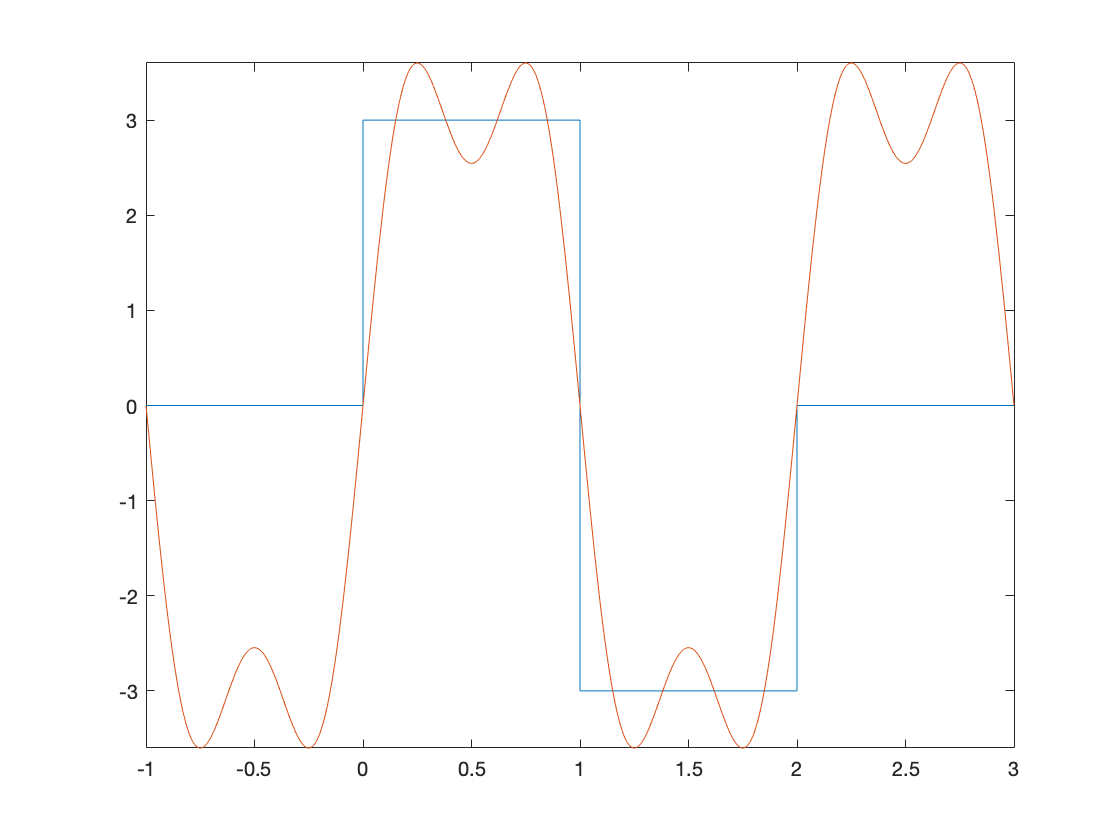

fplot(f, [-1, 3])
hold on
fplot(FourApprox, [-1, 3])
hold off

We can see that the Fourier Series has provided an adequate fit to the periodic function. It's less accurate near the peaks and troughs, so more terms would be desirable if those were the most important aspects.